## **9.1 선형 / 비선형 방정식****연립방정식**


$$f1(x1,x2,\ldots,xn)=0
$$



$$f2(x1,x2,\ldots,xn)=0
$$



$$\vdots 
$$



$$fn(x1,x2,\ldots,xn)=0$$


�**선형방정식**

- 선형방정식은 다음과 같은 일반적인 형태를 가집니다.$f(x) = a_1x_1 + a_2x_2 + \ldots + a_nx_n - b = 0$

**비선형방정식**

- 비선형방정식은 미지수가 일차항의 형태가 아닌 모든 방정식을 의미합니다.

- 예를 들어 다음과 같은 형태가 비선형 방정식의 예시입니다. 

$\begin{cases} x^2 + xy = 10 \\ y + 3xy^2 = 57 \end{cases}$�

- 이를 함수 형태로 표현하면, 

$\begin{cases} u_1(x, y) = x^2 + xy - 10 = 0 \\ u_2(x, y) = y + 3xy^2 - 57 = 0 \end{cases}$�

**9.2 근 찾기 방법**

- 주로 비선형 연립방정식의 경우 **개구간 반복법**을 응용하여 근을 찾습니다.

- 앞서 설명한 고정점 반복법, 뉴턴-랩슨 방법, 혹은 할선법들이 주로 사용됩니다.

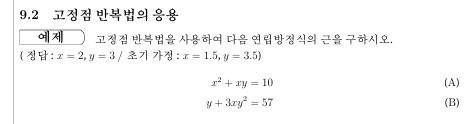

**주어진 연립방정식**


$$x^2 + xy = 10             $$



$$    y + 3xy^2 = 57$$


**초기값**


$$x_0 = 1.5, \quad y_0 = 3.5$$


**고정점 반복법 적용**

고정점 반복법을 적용하여 다음과 같이 반복식을 정리합니다.

**(A) 식에 대한 변환**

$x^2 + xy = 10   \Longrightarrow  x = \sqrt{10 - xy}$�

반복식:

$x_{i+1} = \sqrt{10 - x_i y_i}$��

**(B) 식에 대한 변환**

$y + 3xy^2 = 57 \Longrightarrow  y = \sqrt{\frac{57 - y}{3x}}$��

반복식:

$y_{i+1} = \sqrt{\frac{57 - y_i}{3x_i}}$���

이제 이 반복식을 초기값으로부터 시작하여 근을 찾을 때까지 반복합니다.

**반복 계산 예시**

- **1차 반복**:


$$x_1 = \sqrt{10 - x_0 y_0} = \sqrt{10 - 1.5 \times 3.5} = \sqrt{10 - 5.25} = \sqrt{4.75} \approx 2.18        
                                        $$



$$ y_1 = \sqrt{\frac{57 - y_0}{3x_0}} = \sqrt{\frac{57 - 3.5}{3 \times 1.5}} = \sqrt{\frac{53.5}{4.5}} \approx 3.44$$


- **2차 반복**: 위에서 계산한 $x_1, y_1$� 값을 사용하여 다시 계산을 반복합니다.


$$x_2=\sqrt{10-x1y1}=\sqrt{10-2.18\times 3.44}\approx 1.89$$



$$y_2 = \sqrt{\frac{57 - y_1}{3x_1}} = \sqrt{\frac{57 - 3.44}{3 \times 2.18}} \approx 3.02$$


- 이와 같이 반복을 수행하여 수렴할 때까지 진행합니다.

% 고정점 반복법을 이용한 비선형 연립방정식 풀이

% 초기값 설정
x0 = 1.5;
y0 = 3.5;

% 수렴 오차 및 최대 반복 횟수 설정
tolerance = 1e-6;
max_iter = 100;

% 초기값 할당
x_vals = x0;
y_vals = y0;
x = x0;
y = y0;

% 결과 저장을 위한 변수
results = [];
error_x = inf;
error_y = inf;

% 반복법 수행
for i = 1:max_iter
    % 새로운 값 계산
    x_new = sqrt(10 - x * y);
    y_new = sqrt((57 - y) / (3 * x));
    
    % 상대 오차 계산
    if i > 1
        error_x = abs((x_new - x) / x_new) * 100;
        error_y = abs((y_new - y) / y_new) * 100;
    end
    
    % 평균 상대 오차 계산
    avg_error = (error_x + error_y) / 2;
    
    % 결과 저장 (반복 횟수, x, y, 평균 상대 오차)
    results = [results; i, x_new, y_new, avg_error];
    
    % 반복 과정에서의 값 저장
    x_vals = [x_vals, x_new];
    y_vals = [y_vals, y_new];
    
    % 수렴 여부 확인
    if avg_error < tolerance
        fprintf('수렴 완료: 반복 횟수 = %d\n', i);
        fprintf('근: x = %.6f, y = %.6f\n', x_new, y_new);
        break;
    end
    
    % 업데이트
    x = x_new;
    y = y_new;
end

if i == max_iter
    fprintf('최대 반복 횟수 도달, 수렴하지 않았을 수 있습니다.\n');
end

최대 반복 횟수 도달, 수렴하지 않았을 수 있습니다.



% 결과 표 출력
fprintf('\n(A)\n');


(A)


fprintf('반복횟수\t\tx\t\t\ty\t\t\te_a\n');

반복횟수		x			y			e_a


fprintf('------------------------------------------\n');

------------------------------------------


for k = 1:size(results, 1)
    fprintf('%d\t\t%.4f\t\t%.4f\t\t%.4f\n', results(k, 1), results(k, 2), results(k, 3), results(k, 4));
end

1		2.1794		3.4480		Inf
2		1.5765		2.8619		29.3654
3		2.3427		3.3834		24.0609
4		1.4400		2.7620		42.5912
5		2.4541		3.5433		31.6852
6		1.1421		2.6946		73.1844
7		2.6311		3.9811		44.4533
8		0.0000		2.5917		224.2068
9		3.1748		3.6281		88.8478
10		2.4546		2.3581		126.2391
11		2.5174		2.0847		92.4244
12		2.6063		2.4692		70.8443
13		2.2209		2.5194		60.1138
14		2.3038		2.7040		51.3348
15		2.1611		2.7086		48.8612
16		2.2073		2.7792		45.6060
17		2.1454		2.7724		44.8327
18		2.1712		2.8047		43.3129
19		2.1392		2.7985		42.9423
20		2.1543		2.8160		42.1121
21		2.1359		2.8117		41.8971
22		2.1451		2.8221		41.4039
23		2.1338		2.8193		41.2706
24		2.1396		2.8257		40.9646
25		2.1326		2.8239		40.8798
26		2.1363		2.8280		40.6857
27		2.1318		2.8268		40.6311
28		2.1341		2.8294		40.5062
29		2.1312		2.8286		40.4707
30		2.1328		2.8303		40.3898
31		2.1309		2.8298		40.3666
32		2.1319		2.8309		40.3139
33		2.1307		2.8306		40.2987
34		2.1313		2.8313		40.2643
35		2.1305		2.8311		40.2543
36		2.1309		2.8316		40.2318
37	


% 결과 시각화
figure;
plot(1:i+1, x_vals, '-o', 'LineWidth', 1.5);

hold on;
plot(1:i+1, y_vals, '-x', 'LineWidth', 1.5);

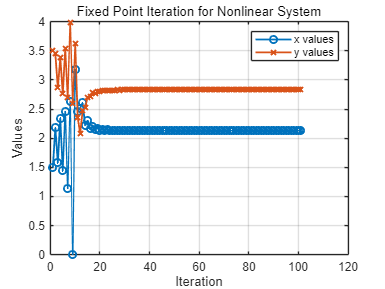

xlabel('Iteration');
ylabel('Values');
legend('x values', 'y values');
title('Fixed Point Iteration for Nonlinear System');
grid on;


% x와 y의 변화를 보여주는 2D 궤적 그래프
figure;
plot(x_vals, y_vals, '-o', 'LineWidth', 1.5);

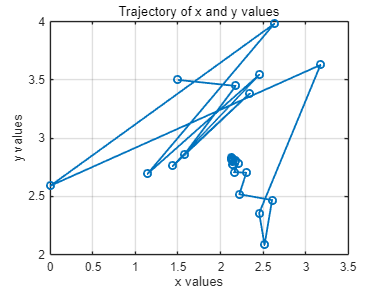

xlabel('x values');
ylabel('y values');
title('Trajectory of x and y values');
grid on;


(A)
반복횟수		x			y			e_a
------------------------------------------
1		2.1794		3.4480		31.1753
2		1.5765		2.8619		38.2503
3		2.3427		3.3834		32.7086
4		1.4400		2.7620		62.6863
5		2.4541		3.5433		41.3216
6		1.1421		2.6946		114.8731
7		2.6311		3.9811		56.5910
8		0.0000		2.5917		394.8048
9		3.1748		3.6281		104.1564
10		2.4546		2.3581		82.5800
11		2.5174		2.0847		135.8633
12		2.6063		2.4692		80.5517
13		2.2209		2.5194		78.2802
14		2.3038		2.7040		66.1614
15		2.1611		2.7086		63.0437
16		2.2073		2.7792		59.7606
17		2.1454		2.7724		58.4033
18		2.1712		2.8047		56.8610
19		2.1392		2.7985		56.2371
20		2.1543		2.8160		55.3388


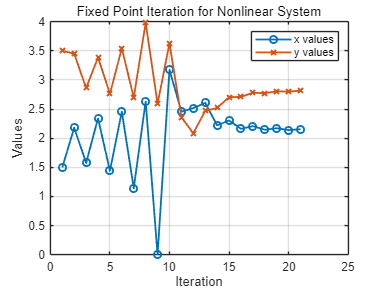

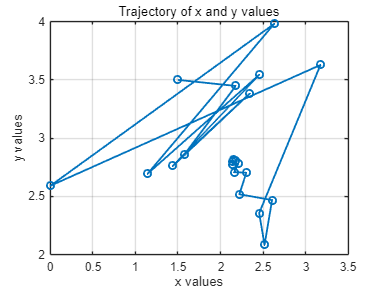

function NA9_2_FixedPoint(x_new, err_s)
    % 주어진 비선형 방정식을 함수 핸들로 정의
    func1 = @(x) sqrt(10 - x(1) * x(2));
    func2 = @(x) sqrt((57 - x(2)) / (3 * x(1)));
    

    % 반복을 최대 20번 수행
    max_iter = 20;
    
    % 결과 저장을 위한 변수
    results = [];
    x_vals = x_new(1);
    y_vals = x_new(2);

    for n = 1:max_iter
        x_old = x_new;
        
        % 새로운 x와 y 값 계산
        x_new(1) = func1(x_old);
        x_new(2) = func2(x_old);
        
        % 상대 오차 계산
        err_a = abs((x_new(1) - x_old(1)) / x_new(1)) * 100;
        
        % 결과 저장
        results = [results; n, x_new(1), x_new(2), err_a];
        
        % 시각화를 위한 값 저장
        x_vals = [x_vals, x_new(1)];
        y_vals = [y_vals, x_new(2)];
        
        % 수렴 조건 확인
        if err_a <= err_s
            fprintf('수렴 완료: 반복 횟수 = %d\n', n);
            break;
        end
    end

    % 결과 표 출력
    fprintf('\n(A)\n');
    fprintf('반복횟수\t\tx\t\t\ty\t\t\te_a\n');
    fprintf('------------------------------------------\n');
    for k = 1:size(results, 1)
        fprintf('%d\t\t%.4f\t\t%.4f\t\t%.4f\n', results(k, 1), results(k, 2), results(k, 3), results(k, 4));
    end

    % 결과 시각화
    figure;
    plot(1:n+1, x_vals, '-o', 'LineWidth', 1.5);
    hold on;
    plot(1:n+1, y_vals, '-x', 'LineWidth', 1.5);
    xlabel('Iteration');
    ylabel('Values');
    legend('x values', 'y values');
    title('Fixed Point Iteration for Nonlinear System');
    grid on;

    % x와 y의 변화를 보여주는 2D 궤적 그래프
    figure;
    plot(x_vals, y_vals, '-o', 'LineWidth', 1.5);
    xlabel('x values');
    ylabel('y values');
    title('Trajectory of x and y values');
    grid on;
end



% 초기값 설정 및 허용 오차 설정
initial_guess = [1.5, 3.5];  % x = 1.5, y = 3.5
tolerance = 1e-3;            % 허용 오차

% 함수 호출
NA9_2_FixedPoint(initial_guess, tolerance);

위의 풀이법에서 수식 제곱근을 사용하지 않고 아래와 같이 바꾸어서 적용할 수도 있습니다.


$$x_{i+1}=\frac{10-x_i^2}{y_i}$$


$y_{i+1}=57-3x_iy_i^2$��

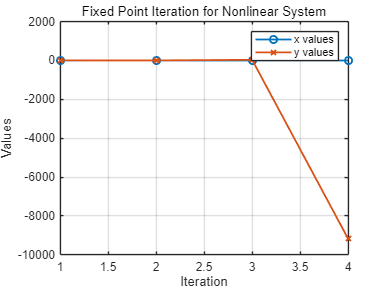

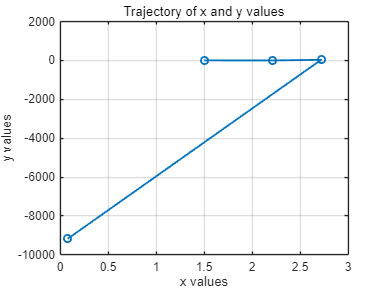


반복 횟수	 x		 y		 상대 오차(%)
-------------------------------------------------
1		 2.214286	 1.875000	 86.666667
2		 2.718367	 33.646205	 94.427306
3		 0.077586	 -9175.123002	 3403.676802


function FixedPointIteration(x0, y0, tol, max_iter)

    % 초기값 설정
    x_vals = x0;
    y_vals = y0;
    x_new = x0;
    y_new = y0;
    results = [];
    
    % 최대 반복 수행
    for n = 1:max_iter
        % 이전 값 저장
        x_old = x_new;
        y_old = y_new;
        
        % 새로운 x와 y 값 계산 (주어진 반복 식에 따라)
        x_new = (10 - x_old^2) / y_old;
        y_new = 57 - 3 * x_old * y_old^2;
        
        % 값의 범위 확인 (오버플로우 방지)
        if abs(x_new) > 1e6 || abs(y_new) > 1e6
            warning('값이 너무 커져 반복을 중단합니다.');
            break;
        end
        
        % 상대 오차 계산
        error = max(abs((x_new - x_old) / x_new) * 100, abs((y_new - y_old) / y_new) * 100);
        
        % 결과 저장
        results = [results; n, x_new, y_new, error];
        
        % 값 저장
        x_vals = [x_vals, x_new];
        y_vals = [y_vals, y_new];
        
        % 수렴 여부 확인
        if error < tol
            fprintf('수렴 완료: 반복 횟수 = %d\n', n);
            fprintf('근: x = %.6f, y = %.6f\n', x_new, y_new);
            break;
        end
    end

    % 결과 시각화 - 반복 횟수에 따른 x, y 변화
    figure;
    plot(1:length(x_vals), x_vals, '-o', 'LineWidth', 1.5);
    hold on;
    plot(1:length(y_vals), y_vals, '-x', 'LineWidth', 1.5);
    xlabel('Iteration');
    ylabel('Values');
    legend('x values', 'y values');
    title('Fixed Point Iteration for Nonlinear System');
    grid on;

    % x와 y의 궤적 시각화
    figure;
    plot(x_vals, y_vals, '-o', 'LineWidth', 1.5);
    xlabel('x values');
    ylabel('y values');
    title('Trajectory of x and y values');
    grid on;
    
    % 결과표 출력
    fprintf('\n반복 횟수\t x\t\t y\t\t 상대 오차(%%)\n');
    fprintf('-------------------------------------------------\n');
    for i = 1:size(results, 1)
        fprintf('%d\t\t %.6f\t %.6f\t %.6f\n', results(i, 1), results(i, 2), results(i, 3), results(i, 4));
    end
end



Iter.		x			y			ε_a
---------------------------------------------------------
1		2.0360		2.8439		2.6327e+01
2		1.9987		3.0023		5.2764e+00
3		2.0000		3.0000		7.6305e-02
4		2.0000		3.0000		1.9554e-05
5		2.0000		3.0000		2.5017e-12


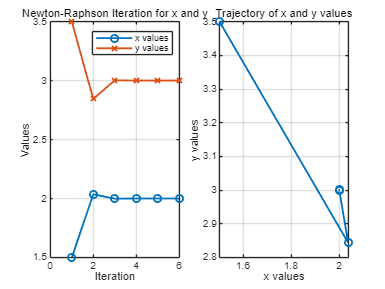

% 초기값 설정 및 허용 오차 설정
initial_x = 1.5;   % x의 초기값

initial_y = 3.5;   % y의 초기값
tolerance = 1e-2;  % 허용 오차
max_iterations = 20; % 최대 반복 횟수

% 함수 호출
FixedPointIteration(initial_x, initial_y, tolerance, max_iterations);

보시는 바와 같이 발산하여 해를 찾을 수 없습니다.

## **고정점 반복법의 수렴 조건**

고정점 반복법이 수렴하기 위한 충분 조건은 다음과 같습니다:

$E_{i+1} = g'(\xi )$�

- 여기서


$$\left| \frac{\partial u}{\partial x} \right| + \left| \frac{\partial u}{\partial y} \right| < 1                          $$



$$\left| \frac{\partial v}{\partial x} \right| + \left| \frac{\partial v}{\partial y} \right| < 1$$


- 가 성립해야 합니다.

## 수렴조건 설명(자세히)

**1. 고정점 반복법의 기본 아이디어**

고정점 반복법은 연립방정식의 근을 찾는 방법 중 하나로, 주어진 함수 $g(x)$를 반복적으로 적용하여 $x = g(x)$을 만족하는 고정점을 찾는 방법입니다. 고정점 반복법은 다음과 같은 반복식을 사용합니다.


$$x_{i+1} = g(x_i)$$


여기서 $x$는 다변수일 수 있으며,$ g(x)$는 연립방정식의 형태를 나타낼 수 있습니다.

**2. 수렴 조건의 유도**

고정점 반복법이 수렴하려면, 초기값$x_0$에서 시작한 값들이 반복될수록 원하는 고정점에 점점 가까워져야 합니다. 이 수렴 조건을 수학적으로 표현하기 위해, 오차$E_i = x_i - x^*$를 정의합니다. 여기서 $x^*$는 실제 고정점(근)입니다.

반복식 $x_{i+1} = g(x_i)$에$x = x^*$를 대입하면:$x^* = g(x^*)$

이므로,


$$E_{i+1} = x_{i+1} - x^* = g(x_i) - g(x^*)$$


테일러 급수를 이용하여 $g(x)$를$x = x^*$에서 1차 근사하면:

$g(x_i) \approx g(x^*) + g'(x^*)(x_i - x^*) = g(x^*) + g'(x^*)E_i$�

따라서,

$E_{i+1} = g'(x^*) E_i$�

이 식을 통해 오차가 수렴하기 위해서는$|g'(x^*)| < 1$이어야 한다는 결론을 얻을 수 있습니다. 즉, 수렴하려면 반복 과정에서 오차의 크기가 점차 작아져야 하기 때문입니다.

**3. 다변수 함수의 경우**

연립방정식에서 미지수가 여러 개일 경우, 고정점 반복법의 수렴 조건은 각 변수에 대한 편미분을 고려해야 합니다. 연립방정식을 다음과 같이 정의한다고 가정합시다:

$\begin{cases} u(x, y) = 0 \\ v(x, y) = 0 \end{cases}$�

그리고 이 연립방정식에 고정점 반복법을 적용한다면,

$\begin{cases} x_{i+1} = g_1(x_i, y_i) \\ y_{i+1} = g_2(x_i, y_i) \end{cases}$�

와 같이 반복식이 주어집니다.

고정점 $(x^*, y^*)$에 대해 수렴 조건을 확인하기 위해서는 편미분을 고려한 Jacobian 행렬을 구성해야 합니다:


$$J=\left\lbrack \begin{array}{cc}
\frac{\vartheta g_1 }{\vartheta x} & \frac{\vartheta g_1 }{\vartheta y}\\
\frac{\vartheta g_2 }{\vartheta x} & \frac{\vartheta g_2 }{\vartheta y}
\end{array}\right\rbrack \;$$


**4. 수렴 조건**

고정점 반복법이 수렴하려면 Jacobian 행렬의 각 행에 대해 다음 조건을 만족해야 합니다:


$$\left| \frac{\partial g_1}{\partial x} \right| + \left| \frac{\partial g_1}{\partial y} \right| < 1                              $$



$$\left| \frac{\partial g_2}{\partial x} \right| + \left| \frac{\partial g_2}{\partial y} \right| < 1$$


이 조건은 각 행의 절대값 합이 1보다 작아야 함을 의미합니다. 이를 통해, 다음과 같은 결론을 얻을 수 있습니다:

- 편미분들의 합이 1보다 작으면, 작은 변화에 대해서도 반복 과정에서 변화가 감소하게 되어 수렴하게 됩니다.

- 반대로 편미분들의 합이 1보다 크다면, 작은 변화가 반복 과정에서 점점 커져 발산할 가능성이 높아집니다.

**제시된 예제에서의 수렴 조건 확인**

- $u(x, y) = \frac{10 - x^2}{y}$** 에서 미분**

$\frac{\partial u}{\partial x} = \frac{-2x}{y}, \quad \frac{\partial u}{\partial y} = -\frac{10 - x^2}{y^2}$�

- 따라서 다음과 같은 수렴 조건을 얻을 수 있습니다:


$$\left| \frac{-2x}{y} \right| + \left| \frac{10 - x^2}{y^2} \right| < 1$$


- 초기값 $(x, y) = (1.5, 3.5)$에서 계산하면 다음과 같은 값이 나옵니다:

- $1.4898$이는 1보다 크기 때문에 이 초기값에서는 수렴 조건을 만족하지 않습니다.

- $(x, y) = (2, 3)$에서 계산하면 2보다 크므로 역시 발산합니다.

- $u(x, y) = \sqrt{10 - xy}$** 에서 미분**


$$\frac{\partial u}{\partial x} = \frac{-y}{2\sqrt{10 - xy}}, \quad \frac{\partial u}{\partial y} = \frac{-x}{2\sqrt{10 - xy}}$$


- �따라서 수렴 조건은 다음과 같이 표현됩니다:


$$\left| \frac{y}{2\sqrt{10 - xy}} \right| + \left| \frac{x}{2\sqrt{10 - xy}} \right| < 1$$


- 위의 수식에 초기조건 $(x, y) = (1.5, 3.5)$을 대입하여 계산하면 1보다 작은 값(0.53) 이 나옵니다.

- 따라서 위의 수식은 수렴하는 것을 확인할 수 있습니다.

**결론**

- 고정점 반복법이 수렴하려면 위의 수렴 조건을 반드시 만족해야 합니다.

- 초기값의 선택이 중요하며, 수렴 조건을 확인하여 적절한 초기값을 선택해야 합니다.

## **연립방정식에 대한 Newton-Raphson 방법의 유도 과정**

**1. Newton-Raphson 방법의 기본 원리**

단일 변수 함수$ f(x)$에 대한 Newton-Raphson 방법의 기본 식은 다음과 같습니다:


$$f(x) \approx f(x_i) + (x - x_i) f'(x_i)$$


여기서 테일러 급수 전개를 이용하여 함수$ f(x)$를 근사합니다.

이를 $f(x) = 0$으로 근을 찾는다고 가정하면,


$$f(x_{i+1}) \approx f(x_i) + (x_{i+1} - x_i) f'(x_i) = 0$$


이 식을 정리하면 다음의 반복식을 얻을 수 있습니다:


$$x_{i+1} = x_i - \frac{f(x_i)}{f'(x_i)}$$


�**2. 다변수 연립방정식에 적용**

이제 다변수 함수$f(x, y)$에 대한 Newton-Raphson 방법을 적용하면,


$$f(x, y) \approx f(x_i, y_i) + (x - x_i) \frac{\partial f}{\partial x} + (y - y_i) \frac{\partial f}{\partial y}$$


가 됨을 알수 있습니다.

�

이제 두 개의 미지수 $x$와 $y$를 가지는 두 개의 비선형 방정식의 경우를 생각해봅시다:

$\begin{cases} u(x, y) = 0 \\ v(x, y) = 0 \end{cases}$�

각 함수 $u(x, y)$와 $v(x, y)$를 $(x_i, y_i)$에서 테일러 급수로 전개하여 1차 근사하면 다음과 같습니다:


$$u(x_{i+1}, y_{i+1}) \approx u(x_i, y_i) + \frac{\partial u}{\partial x}(x_{i+1} - x_i) + \frac{\partial u}{\partial y}(y_{i+1} - y_i)$$



$$v(x_{i+1}, y_{i+1}) \approx v(x_i, y_i) + \frac{\partial v}{\partial x}(x_{i+1} - x_i) + \frac{\partial v}{\partial y}(y_{i+1} - y_i)$$


여기서 $u(x_{i+1}, y_{i+1}) = 0$ 및 $v(x_{i+1}, y_{i+1}) = 0$이라고 가정하면:


$$0 = u(x_i, y_i) + \frac{\partial u}{\partial x}(x_{i+1} - x_i) + \frac{\partial u}{\partial y}(y_{i+1} - y_i)$$



$$0 = v(x_i, y_i) + \frac{\partial v}{\partial x}(x_{i+1} - x_i) + \frac{\partial v}{\partial y}(y_{i+1} - y_i)$$


이 두 식을 각각 정리하면:


$$\frac{\partial u}{\partial x}(x_{i+1} - x_i) + \frac{\partial u}{\partial y}(y_{i+1} - y_i) = -u(x_i, y_i)$$



$$\frac{\partial v}{\partial x}(x_{i+1} - x_i) + \frac{\partial v}{\partial y}(y_{i+1} - y_i) = -v(x_i, y_i)$$


**3. 연립방정식으로 표현**

위 식은 연립방정식의 형태를 가지며 다음과 같이 행렬 방정식으로 나타낼 수 있습니다:


$$\left\lbrack \begin{array}{cc}
\frac{\vartheta u}{\vartheta x} & \frac{\vartheta u}{\vartheta y}\\
\frac{\vartheta v}{\vartheta x} & \frac{\vartheta v}{\vartheta y}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_{i+1} -x_i \\
y_{i+1} -y_i 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-u\left(x_i ,y_i \right)\\
-v\left(x_i ,y_i \right)
\end{array}\right\rbrack$$


**4. 미지수 **$x_{i+1}$**과 **$y_{i+1}$**를 구하기 위해 행렬의 역행렬 사용**

위의 식을 역행렬을 사용하여 풀면:


$$\left\lbrack \begin{array}{c}
x_{i+1} -x_i \\
y_{i+1} -y_i 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{cc}
\frac{\vartheta u}{\vartheta x} & \frac{\vartheta u}{\vartheta y}\\
\frac{\vartheta v}{\vartheta x} & \frac{\vartheta v}{\vartheta y}
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
-u\left(x_i ,y_i \right)\\
-v\left(x_i ,y_i \right)
\end{array}\right\rbrack$$


행렬의 역행렬을 계산하면 다음과 같은 결과를 얻습니다:


$$x_{i+1} = x_i - \frac{u \frac{\partial v}{\partial y} - v \frac{\partial u}{\partial y}}{\frac{\partial u}{\partial x}\frac{\partial v}{\partial y} - \frac{\partial u}{\partial y}\frac{\partial v}{\partial x}}$$



$$y_{i+1} = y_i - \frac{v \frac{\partial u}{\partial x} - u \frac{\partial v}{\partial x}}{\frac{\partial u}{\partial x}\frac{\partial v}{\partial y} - \frac{\partial u}{\partial y}\frac{\partial v}{\partial x}}$$


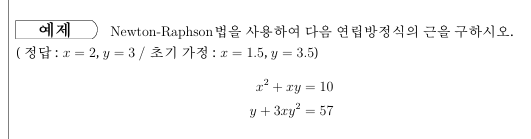

**주어진 연립방정식**

연립방정식은 다음과 같습니다:

$\begin{cases} x^2 + xy = 10 \\ y + 3xy^2 = 57 \end{cases}$�

이를 다음과 같이 두 함수 $u(x, y)$와 $v(x, y)$로 표현할 수 있습니다:


$$u(x, y) = x^2 + xy - 10           $$



$$  v(x, y) = y + 3xy^2 - 57$$


**1. 각 함수의 편미분 계산**

$u(x, y) = x^2 + xy - 10$**의 편미분**


$$\frac{\partial u}{\partial x} = 2x + y      $$



$$        \frac{\partial u}{\partial y} = x                                       
$$


$           v(x, y) = y + 3xy^2 - 57$**의 편미분**


$$\frac{\partial v}{\partial x} = 3y^2          $$



$$    \frac{\partial v}{\partial y} = 1 + 6xy$$


**2. Jacobian 행렬 구성**

연립방정식의 Newton-Raphson 방법에서는 편미분을 이용한 Jacobian 행렬 $J$를 구성합니다. 행렬은 다음과 같습니다:


$$J=\left\lbrack \begin{array}{cc}
\frac{\vartheta u}{\vartheta x} & \frac{\vartheta u}{\vartheta y}\\
\frac{\vartheta v}{\vartheta x} & \frac{\vartheta v}{\vartheta y}
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
2x+y & x\\
3y^2  & 1+6\mathrm{xy}
\end{array}\right\rbrack$$


**3. Newton-Raphson 반복식 적용**

Newton-Raphson 방법을 이용하여 $x
$와$ y$의 값을 업데이트하는 반복식을 도출합니다. 기본적인 Newton-Raphson 방법은 다음과 같이 표현됩니다:


$$\left\lbrack \begin{array}{c}
x_{i+1} \\
y_{i+1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_i \\
y_i 
\end{array}\right\rbrack -J^{-1} \left\lbrack \begin{array}{c}
u\left(x_i ,y_i \right)\\
v\left(x_i ,y_i \right)
\end{array}\right\rbrack$$


**Jacobian 행렬의 역행렬 계산**

Jacobian 행렬의 역행렬은 다음과 같이 계산됩니다:


$$-J^{-1} =\frac{1}{D}\left\lbrack \begin{array}{cc}
1+6\mathrm{xy} & -x\\
-3y^2  & 2x+y
\end{array}\right\rbrack$$


여기서 $D$는 행렬식으로,


$$D = (2x + y)(1 + 6xy) - (3y^2)(x)$$


**Newton-Raphson 방법을 이용한 반복 과정**

- 초기값으로 $(x_0, y_0) = (1.5, 3.5)$를 사용합니다.

- 각 반복 단계에서 $u(x, y)$와 $v(x, y)$, 그리고 Jacobian 행렬을 계산하고, Newton-Raphson 식을 이용하여 $x$와 $y$를 업데이트합니다.

- $x_{i+1}$와 $y_{i+1}$가 수렴할 때까지 이 과정을 반복합니다.

��

Convergence achieved at iteration 5.

Iter.		x			y			ε_a
---------------------------------------------------------
1		2.0360		2.8439		2.6327e+01
2		1.9987		3.0023		5.2764e+00
3		2.0000		3.0000		7.6305e-02
4		2.0000		3.0000		1.9554e-05
5		2.0000		3.0000		2.5017e-12


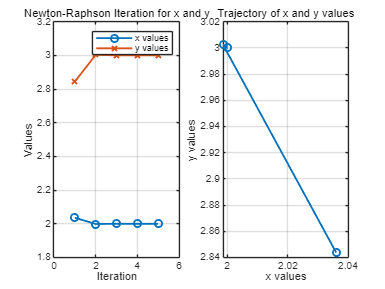

% Newton-Raphson Method for solving the nonlinear system of equations
% Given equations: 
%   x^2 + xy = 10
%   y + 3xy^2 = 57

function NewtonRaphsonMethod()

    % 초기값 설정
    x0 = 1.5;
    y0 = 3.5;
    
    % 수렴 기준 및 최대 반복 횟수 설정
    tol = 1e-6;
    max_iter = 100;
    
    % 결과 저장을 위한 배열
    results = [];
    
    % 초기값 할당
    x_vals = [x0];
    y_vals = [y0];
    
    % 반복 시작
    for iter = 1:max_iter
        % u(x, y)와 v(x, y) 계산
        u = x0^2 + x0 * y0 - 10;
        v = y0 + 3 * x0 * y0^2 - 57;
        
        % 편미분 계산
        Dxu = 2 * x0 + y0;
        Dyu = x0;
        Dxv = 3 * y0^2;
        Dyv = 1 + 6 * x0 * y0;
        
        % Jacobian의 행렬식 계산
        detJ = Dxu * Dyv - Dyu * Dxv;
        
        % Newton-Raphson 식을 이용하여 x와 y 값 업데이트
        x1 = x0 - (u * Dyv - v * Dyu) / detJ;
        y1 = y0 - (v * Dxu - u * Dxv) / detJ;
        
        % 수렴 여부 확인 및 상대 오차 계산
        ea = max(abs((x1 - x0) / x1), abs((y1 - y0) / y1)) * 100;
        
        % 결과 저장
        results = [results; iter, x1, y1, ea];
        
        % 값 업데이트
        x0 = x1;
        y0 = y1;
        
        % 값 저장
        x_vals = [x_vals, x0];
        y_vals = [y_vals, y0];
        
        % 수렴 조건 확인
        if ea < tol
            break;
        end
    end

    % 결과가 수렴하지 않았을 경우
    if iter == max_iter
        warning('최대 반복 횟수에 도달했습니다. 수렴하지 않을 수 있습니다.');
    end

    % 결과 표 출력
    fprintf('\nIter.\t\tx\t\t\ty\t\t\tε_a\n');
    fprintf('---------------------------------------------------------\n');
    for k = 1:size(results, 1)
        fprintf('%d\t\t%.4f\t\t%.4f\t\t%.4e\n', results(k, 1), results(k, 2), results(k, 3), results(k, 4));
    end

    % 결과 시각화
    figure;
    
    % Iteration별 x와 y 변화
    subplot(1, 2, 1);
    plot(1:length(x_vals), x_vals, '-o', 'LineWidth', 1.5, 'DisplayName', 'x values');
    hold on;
    plot(1:length(y_vals), y_vals, '-x', 'LineWidth', 1.5, 'DisplayName', 'y values');
    xlabel('Iteration');
    ylabel('Values');
    title('Newton-Raphson Iteration for x and y');
    legend;
    grid on;
    
    % x와 y의 궤적을 보여주는 그래프
    subplot(1, 2, 2);
    plot(x_vals, y_vals, '-o', 'LineWidth', 1.5);
    xlabel('x values');
    ylabel('y values');
    title('Trajectory of x and y values');
    grid on;
end




NewtonRaphsonMethod();

% Newton-Raphson Method for Nonlinear System of Equations

function NA9_3_NewtonRaphson(x_new, err_s)
    % Define the functions u(x, y) and v(x, y)
    func_u = @(x) x(1)^2 + x(1) * x(2) - 10;
    func_v = @(x) x(2) + 3 * x(1) * x(2)^2 - 57;
    
    % Define the partial derivatives of u and v
    dxfunc_u = @(x) 2 * x(1) + x(2);
    dyfunc_u = @(x) x(1);
    dxfunc_v = @(x) 3 * x(2)^2;
    dyfunc_v = @(x) 1 + 6 * x(1) * x(2);
    
    % Maximum number of iterations
    max_iter = 20;
    
    % Initialize results storage
    results = [];
    
    % Start iterations
    for n = 1:max_iter
        x_old = x_new; % Store old values
        
        % Evaluate the functions
        fu = func_u(x_new);
        fv = func_v(x_new);
        
        % Evaluate the partial derivatives
        dxfu = dxfunc_u(x_new);
        dyfu = dyfunc_u(x_new);
        dxfv = dxfunc_v(x_new);
        dyfv = dyfunc_v(x_new);
        
        % Calculate the Jacobian determinant
        Jf = dxfu * dyfv - dyfu * dxfv;
        
        % Update x and y using Newton-Raphson formulas
        x_new(1) = x_new(1) - (fu * dyfv - fv * dyfu) / Jf;
        x_new(2) = x_new(2) - (fv * dxfu - fu * dxfv) / Jf;
        
        % Calculate the relative error
        err_a = max(abs((x_new - x_old) ./ x_new)) * 100; % Adjusted for multi-variable
        
        % Store results
        results = [results; n, x_new(1), x_new(2), err_a];
        
        % Check convergence
        if err_a <= err_s
            fprintf('Convergence achieved at iteration %d.\n', n);
            break;
        end
    end
    
    % If maximum iterations reached
    if n == max_iter
        warning('Maximum iterations reached without convergence.');
    end
    
    % Display results in tabular format
    fprintf('\nIter.\t\tx\t\t\ty\t\t\tε_a\n');
    fprintf('---------------------------------------------------------\n');
    for k = 1:size(results, 1)
        fprintf('%d\t\t%.4f\t\t%.4f\t\t%.4e\n', results(k, 1), results(k, 2), results(k, 3), results(k, 4));
    end
    
    % Plot the results
    figure;
    
    % Iteration-based plot for x and y values
    subplot(1, 2, 1);
    plot(1:length(results(:, 1)), results(:, 2), '-o', 'LineWidth', 1.5, 'DisplayName', 'x values');
    hold on;
    plot(1:length(results(:, 1)), results(:, 3), '-x', 'LineWidth', 1.5, 'DisplayName', 'y values');
    xlabel('Iteration');
    ylabel('Values');
    title('Newton-Raphson Iteration for x and y');
    legend;
    grid on;
    
    % Trajectory plot for x and y values
    subplot(1, 2, 2);
    plot(results(:, 2), results(:, 3), '-o', 'LineWidth', 1.5);
    xlabel('x values');
    ylabel('y values');
    title('Trajectory of x and y values');
    grid on;
end

NA9_3_NewtonRaphson([1.5, 3.5], 1e-6);
